train = readtable("C:\Users\drami\Desktop\projekt\train.csv");

val = readtable("C:\Users\drami\Desktop\projekt\val.csv");

test = readtable("C:\Users\drami\Desktop\projekt\test.csv");

XTrain = table2array (removevars(train, "spotPrice"));
TTrain = train{:, "spotPrice"};

XVal = table2array (removevars(val, "spotPrice") );
TVal = val{:, "spotPrice"};

XTest = table2array (removevars(test, "spotPrice"));
TTest = test{:, "spotPrice"};

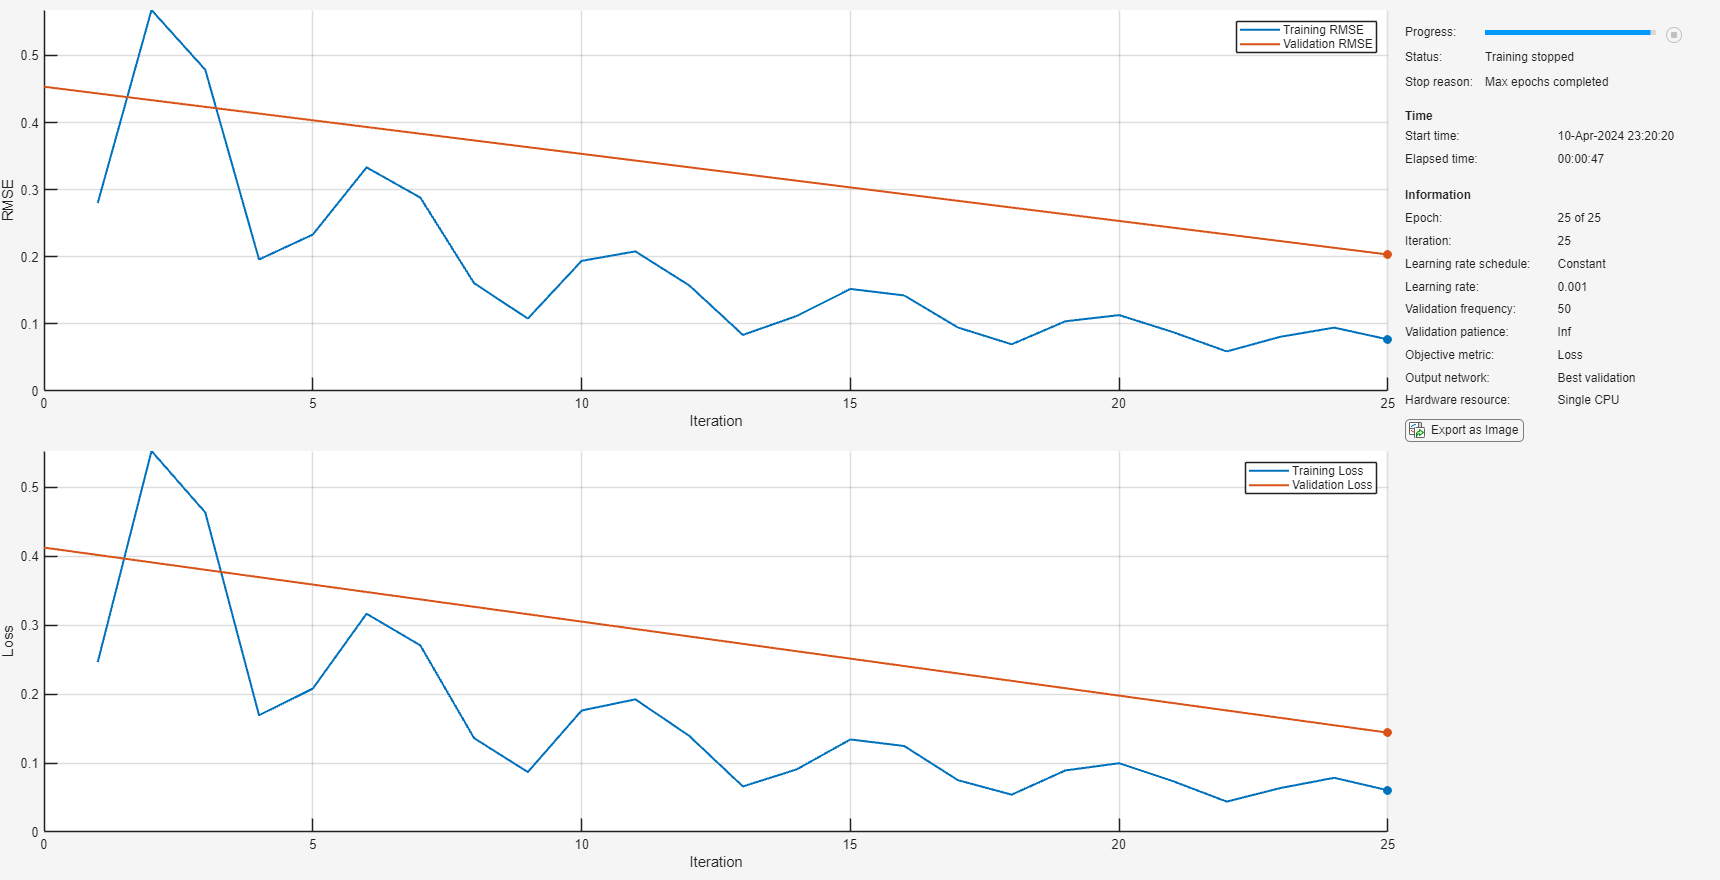

layers = [
    sequenceInputLayer(112)
    lstmLayer(128)
    fullyConnectedLayer(1)];


options = trainingOptions("adam", ...
    MaxEpochs=25, ...
    SequencePaddingDirection="left", ...
    Shuffle="every-epoch", ...
    ValidationData={XVal, TVal}, ...
    Metrics="rmse", ...
    Plots="training-progress", ...
    Verbose=false);


net = trainnet(XTrain,TTrain,layers,"mae",options);

YPred = predict(net, XTest)

YPred = 10200×1 single column vector
    0.0159
    0.0307
    0.0124
    0.0380
    0.0426
    0.0479
    0.0185
    0.0351
    0.0645
    0.0630


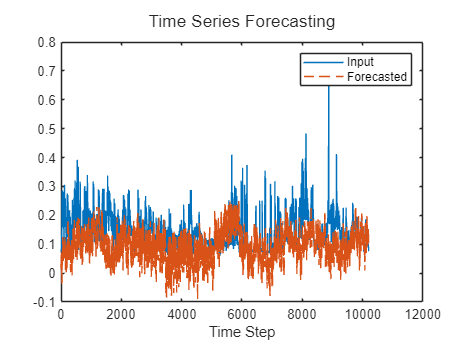

figure
l = tiledlayout(1,1);
title(l,"Time Series Forecasting")
nexttile
plot(TTest)
hold on
plot(YPred,"--")

xlabel("Time Step")
legend(["Input" "Forecasted"])

X = XTest(1, :);
T = TTest(1);

net = resetState(net);
offset = size(X, 1);
[Z, state] = predict(net, X(1:offset, :));
net.State = state;

numPredictionTimeSteps = 120;
Y = zeros(numPredictionTimeSteps,112);

Y(1,:) = Z(end,:);

for t = 2:numPredictionTimeSteps
    [Y(t,:),state] = predict(net,Y(t-1,:));
    net.State = state;
end

numTimeSteps = offset + numPredictionTimeSteps;


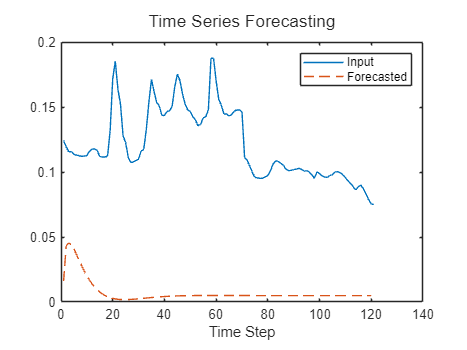

figure
l = tiledlayout(1,1);
title(l,"Time Series Forecasting")
nexttile
plot(TTest(10080:end,1))
hold on
plot(Y(:,1),"--")

xlabel("Time Step")
legend(["Input" "Forecasted"])

net = resetState(net);

[Z,state] = predict(net, x_val_scaled);
net.State = state;


numPredictionTimeSteps = 120

numPredictionTimeSteps = 120


Y = zeros(numPredictionTimeSteps, 110);
Y(1,:) = Z(end,:);

for t = 2:numPredictionTimeSteps
    [Y(t,:), state] = predict(net, Y(t-1, :));
    net.State = state;
end


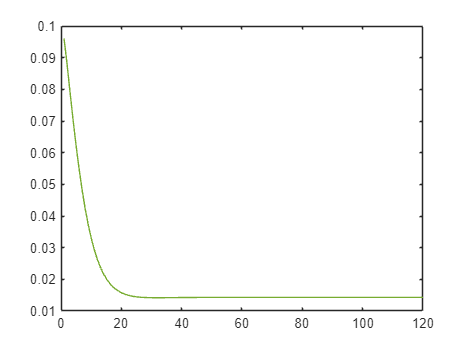

clf
plot(Y)